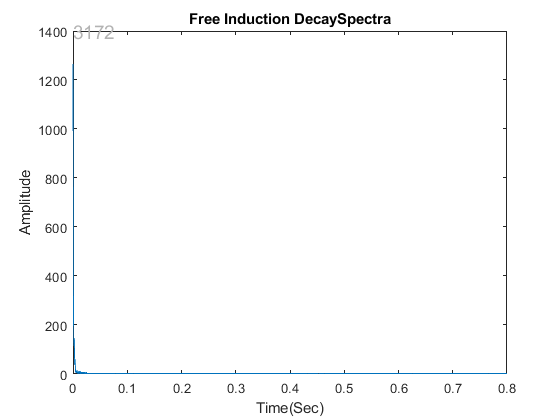

%q1
clear all; close all; clc;
filename = 'shimmed_spectra';
sfrq = 200.228e+6;
SW = 20000;
tacq = 0.8;
Npts = 16000;

time = linspace(0,tacq,Npts);
freq = linspace(sfrq- SW/2,sfrq + SW/2, Npts);
Conversion_Hz_to_PPM = sfrq/1e+6;
freq_ppm = (freq-sfrq)/Conversion_Hz_to_PPM;
kspace1 = loadfid(filename);
fid1 = fft(fftshift(kspace1));

%FID
figure;
plot(time,abs(kspace1));
xlabel('Time(Sec)'),ylabel('Amplitude'),
    title('Free Induction DecaySpectra')
watermark_image('3172');

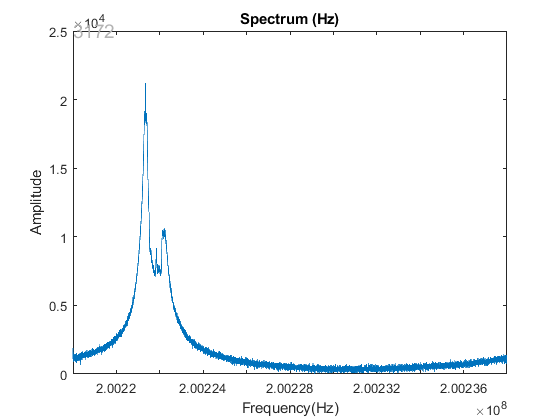


%SPEC IN PPM
figure;
plot(freq,abs(fid1));
xlabel('Frequency(Hz)'),ylabel('Amplitude'),
    title('Spectrum (Hz)')
    watermark_image('3172');

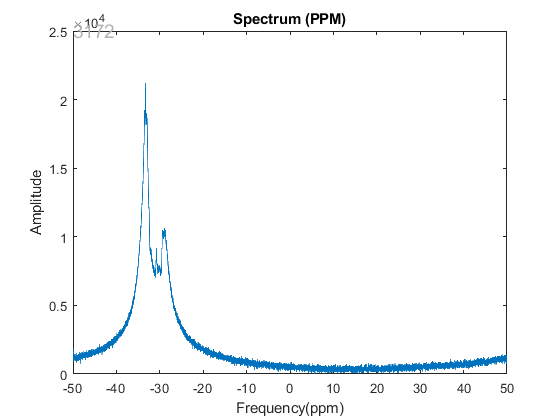

 
%SPEC IN HZ
figure;
plot(freq_ppm,abs(fid1));
xlabel('Frequency(ppm)'),ylabel('Amplitude'),
    title('Spectrum (PPM)')
    watermark_image('3172')

%0 
clear
close all;
filename = '502_Dixon_0';
kspace = loadfid(filename);
kspace_real = abs(kspace);
image1 = fftshift(ifft2(fftshift(kspace)));

image1abs = abs(image1);
image1phase = atan2(imag(image1),real(image1))*180/pi;

testangle = angle(image1);

isequal(image1phase,angle(image1))

ans = logical
   0


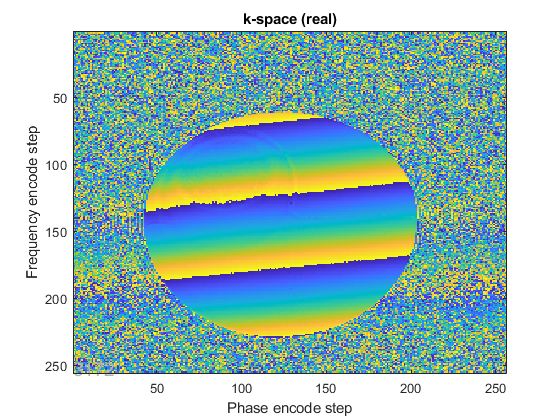


imagesc(image1phase)
title('k-space (real)')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap("default")


imagesc(testangle )
title('k-space (real)')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap("default")

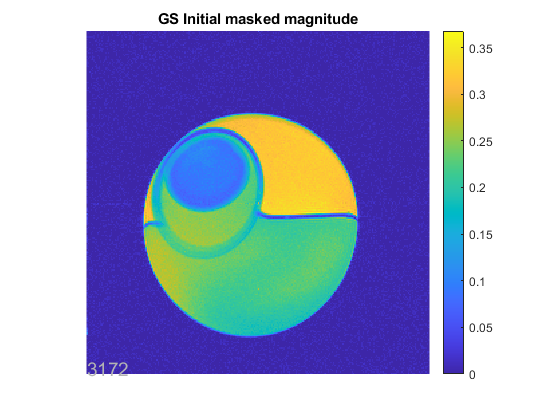

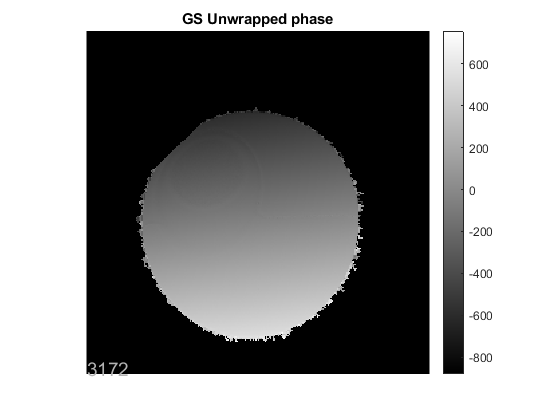


GoldsteinUnwrap2D_r1adj

phase_0 = im_unwrapped;
mag_0 = im_mag.*im_mask;
complex_0 = image1;

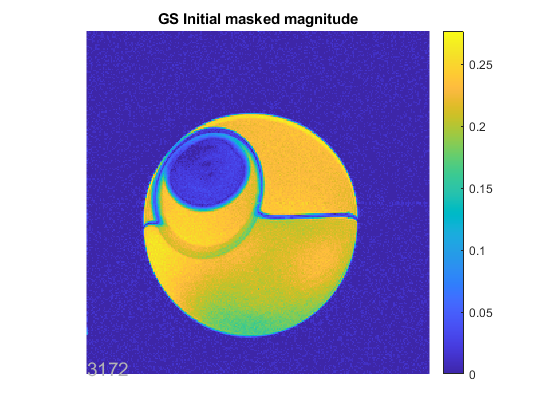

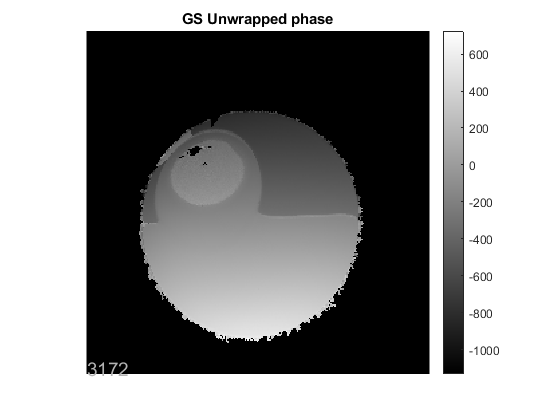

%180
close all;
filename = '502_Dixon_180';
kspace = loadfid(filename);
kspace_real = abs(kspace);
image1 = fftshift(ifft2(fftshift(kspace)));
image1abs = abs(image1);
image1phase = atan2(imag(image1),real(image1))*180/pi;

GoldsteinUnwrap2D_r1adj

phase_180 = im_unwrapped;
mag_180 = im_mag.*im_mask;
complex_180 = image1;

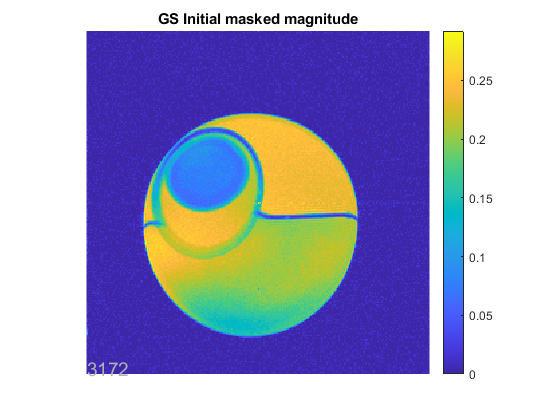

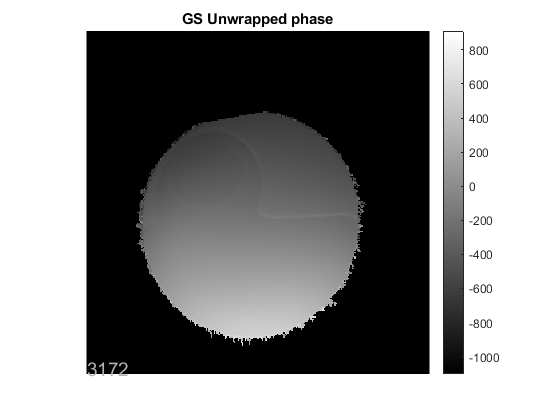

%360
close all;
filename = '502_Dixon_360';
kspace = loadfid(filename);
kspace_real = abs(kspace);
image1 = fftshift(ifft2(fftshift(kspace)));
image1abs = abs(image1);
image1phase = atan2(imag(image1),real(image1))*180/pi;

GoldsteinUnwrap2D_r1adj

phase_360 = im_unwrapped;
mag_360 = im_mag.*im_mask;

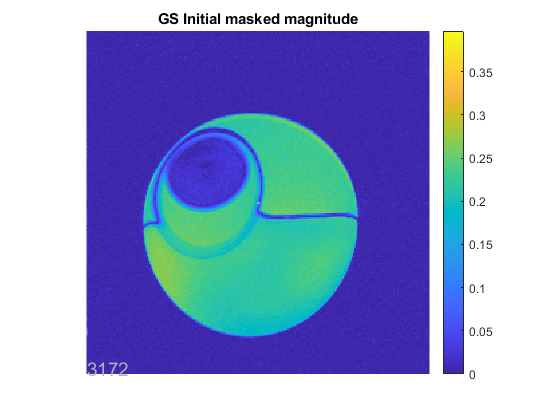

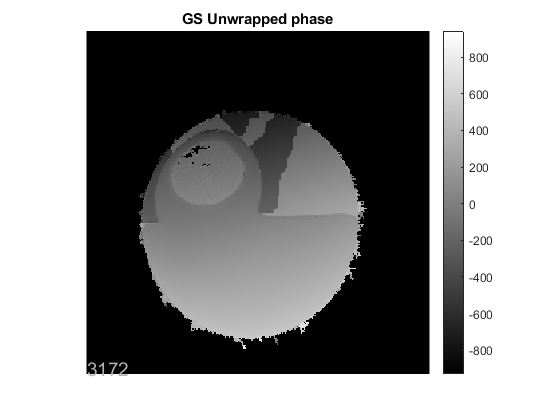

%-180
close all;
filename = '502_Dixon_neg180';
kspace = loadfid(filename);
kspace_real = abs(kspace);
image1 = fftshift(ifft2(fftshift(kspace)));
image1abs = abs(image1);
image1phase = atan2(imag(image1),real(image1))*180/pi;

GoldsteinUnwrap2D_r1adj

phase_n180 = im_unwrapped;
mag_n180 = im_mag.*im_mask;
complex_n180 = image1;

%THREE POINT DIXON
%Two point dixon isnt missing it just comes after

%pre definied shift, same for all
shift1 = 0

shift1 = 0

shift2 = 0

shift2 = 0

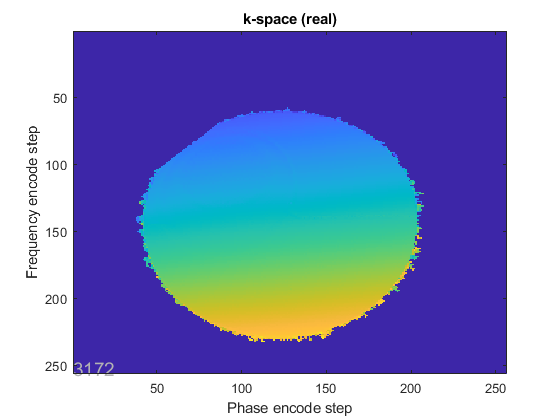


%verifying shift centers image
imagesc(phase_0)
title('k-space (real)')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap("default")


phase_0 = circshift(phase_0,shift1,1);
phase_0 = circshift(phase_0,shift2,2);

imagesc(phase_0)
title('k-space (real)')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap("default")

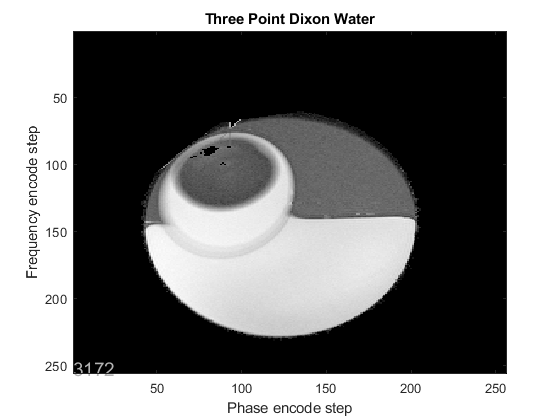

%shift verified


%apply shift to everything we are going to use
phase_360 = circshift(phase_360,shift1,1);
phase_360 = circshift(phase_360,shift2,2);

%phase difference 360 & 0
phase_dif1 = (phase_360 - phase_0)/2;

%more shifting
phase_180 = circshift(phase_180,shift1,1);
phase_180 = circshift(phase_180,shift2,2);
mag_180 = circshift(mag_180,shift1,1);
mag_180 = circshift(mag_180,shift2,2);

%final phase subtraction
phaseTPD = phase_180 - phase_dif1;

%reconnstruct 180 complex
TPDcomplex = zeros(256);
for o = 1:256
    for p = 1:256
        temprad = deg2rad(phaseTPD(o,p));
        if (isnan(mag_180(o,p)))
            TPDcomplex(o,p) = NaN
        else
            [realA,imagB] = pol2cart(temprad,mag_180(o,p));
            TPDcomplex(o,p) = realA + 1i*imagB;
        end
    end
end



%shift complex data for 0 pulse
complex_0 = circshift(complex_0,shift1,1);
complex_0 = circshift(complex_0,shift2,2);

%apply 3 point dixon
TPDW = (1/2)*(complex_0 + TPDcomplex)
TPDF = (1/2)*(complex_0 - TPDcomplex)

%plot out 3 point dixon
figure;
imagesc(abs(TPDW))
title('Three Point Dixon Water')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)

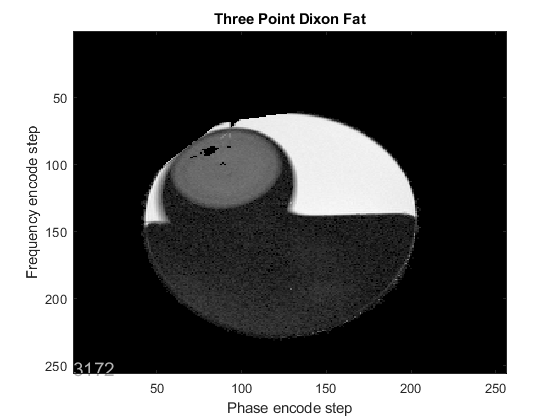


figure;
imagesc(abs(TPDF))
title('Three Point Dixon Fat')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)

% only do this if your phase is in degrees
temprad = deg2rad(phaseTPD);
%

[realA,imagB] = pol2cart(temprad,mag_180);
alternatecorrected180 = realA + i*imagB;
% isequal(alternatecorrected180,TPDcomplex)

ans = logical
   0


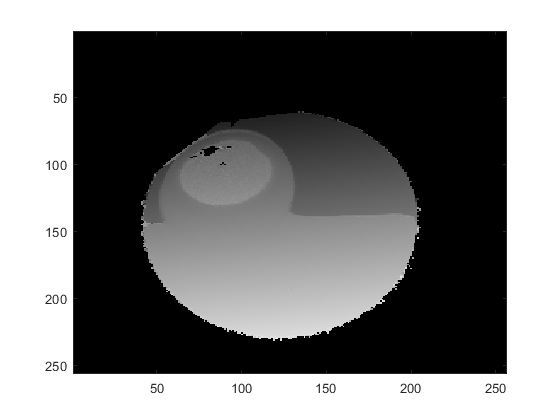

% 
% figure;
% imagesc(temprad)
% colormap(gray)

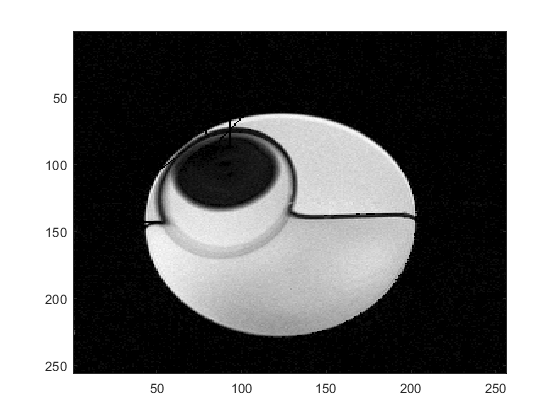


%apply 3 point dixon
TPDW = (1/2)*(complex_0 + alternatecorrected180)
TPDF = (1/2)*(complex_0 - alternatecorrected180)

figure;
imagesc(mag_180)
colormap(gray)

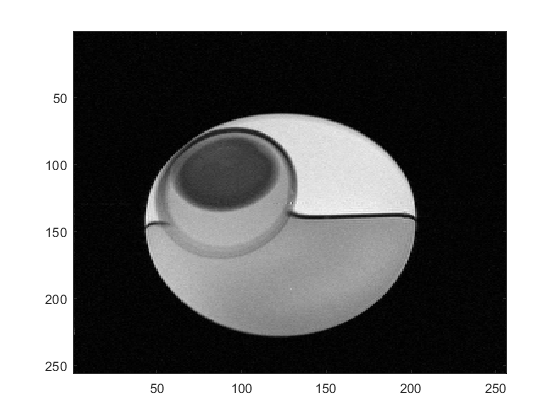


figure;
imagesc(abs(complex_0))
colormap(gray)

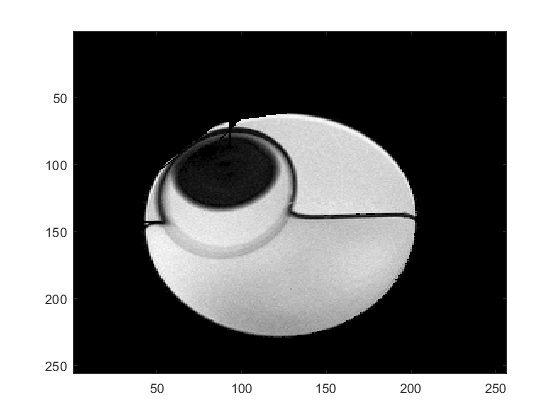


figure;
imagesc(abs(alternatecorrected180))
colormap(gray)


%plot out 3 point dixon
figure;
imagesc(abs(TPDW))
title('Three Point Dixon Water')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)


figure;
imagesc(abs(TPDF))
title('Three Point Dixon Fat')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)

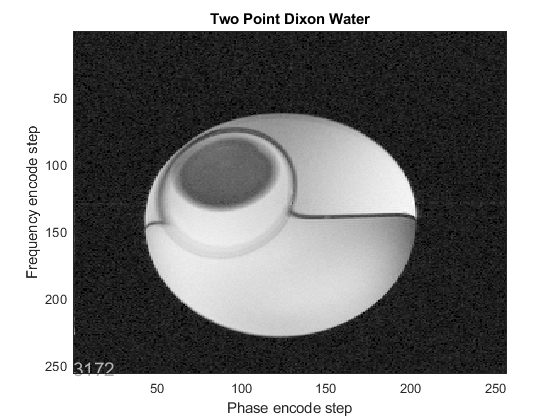

%TWO POINT DIXON
%shift complex 180 using amounts from 3 point dixon
complex_180 = circshift(complex_180,shift1,1);
complex_180 = circshift(complex_180,shift2,2);

%two point dixon formulas
PDW = (1/2)*(complex_0 + complex_180);
PDF = (1/2)*(complex_0 - complex_180);

%plot out 2 point dixon
figure;
imagesc(abs(PDW))
title('Two Point Dixon Water')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)

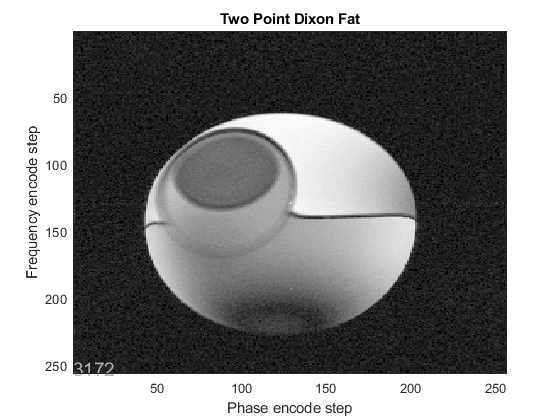


figure;
imagesc(abs(PDF))
title('Two Point Dixon Fat')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)

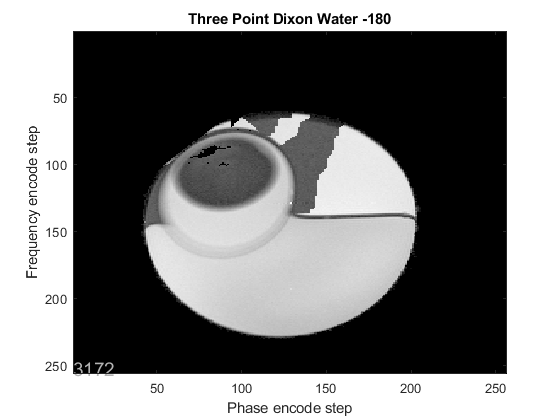

%Three point dixon but with -180 0 180

%shift
phase_n180 = circshift(phase_n180,shift1,1);
phase_n180 = circshift(phase_n180,shift2,2);

mag_0 = circshift(mag_0,shift1,1);
mag_0 = circshift(mag_0,shift2,2);

%subtract phases
phase_dif1 = (phase_180 - phase_n180)/2;
phaseTPD = phase_0 - phase_dif1;

%reconnstruct complex image of 0
TPDcomplex = zeros(256);
for o = 1:256
    for p = 1:256
        temprad = deg2rad(phaseTPD(o,p));
        if (isnan(mag_0(o,p)))
            TPDcomplex(o,p) = NaN
        else
            [realA,imagB] = pol2cart(temprad,mag_0(o,p));
            TPDcomplex(o,p) = realA + 1i*imagB;
        end
    end
end

%shift
complex_n180 = circshift(complex_n180,shift1,1);
complex_n180 = circshift(complex_n180,shift2,2);

%two point formula
TPDW = (1/2)*(complex_n180 + TPDcomplex)
TPDF = (1/2)*(complex_n180 - TPDcomplex)

%plot out 3 point dixon
figure;
imagesc(abs(TPDW))
title('Three Point Dixon Water -180')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)

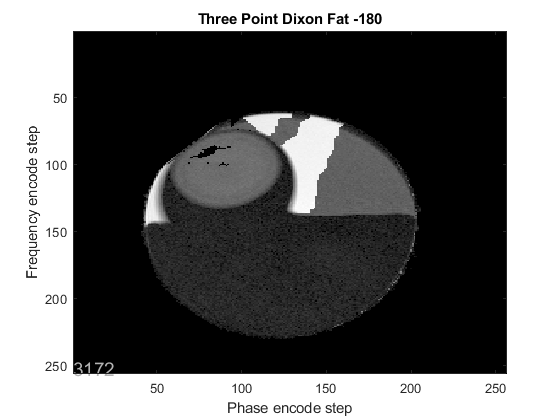


figure;
imagesc(abs(TPDF))
title('Three Point Dixon Fat -180')
xlabel('Phase encode step')
ylabel('Frequency encode step')
watermark_image('3172')
colormap(gray)
brighten(0.5)